# Machine Learning Online Class

## Initialization

clear ; close all; clc;

## =========== Part 1: Loading and Visualizing Data =============

% Load Training Data
fprintf('Loading and Visualizing Data ...\n')

Loading and Visualizing Data ...


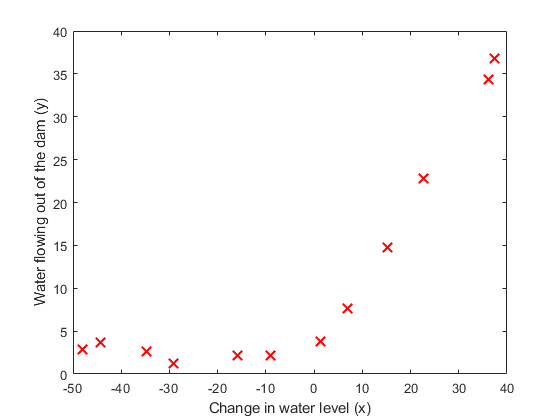


% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment
load ('ex5data1.mat');

% m = Number of examples
m = size(X, 1);

% Plot training data
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');

## =========== Part 2: Regularized Linear Regression Cost =============

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);

fprintf(['Cost at theta = [1 ; 1]: %f '...
         '\n(this value should be about 303.993192)\n'], J);

Cost at theta = [1 ; 1]: 303.993192 
(this value should be about 303.993192)


## =========== Part 3: Regularized Linear Regression Gradient =============

theta = [1 ; 1];
[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);

fprintf(['Gradient at theta = [1 ; 1]:  [%f; %f] '...
         '\n(this value should be about [-15.303016; 598.250744])\n'], ...
         grad(1), grad(2));

Gradient at theta = [1 ; 1]:  [-15.303016; 598.250744] 
(this value should be about [-15.303016; 598.250744])


## =========== Part 4: Train Linear Regression =============

%  Train linear regression with lambda = 0
lambda = 0;
theta = trainLinearReg([ones(m, 1), X], y, lambda);

Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01
Iteration     3 | Cost: 2.237391e+01
Iteration     4 | Cost: 2.237391e+01


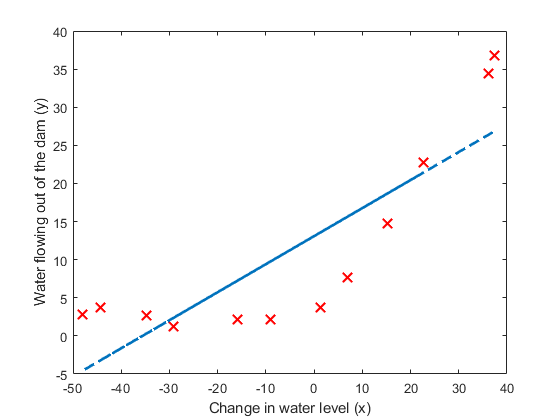


%  Plot fit over the data
% 原始数据
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
hold on;
% 拟合曲线
plot(X, [ones(m, 1), X] * theta, '--', 'LineWidth', 2)
hold off

## =========== Part 5: Learning Curve for Linear Regression =============

lambda = 0;
[error_train, error_val] = ...
    learningCurve([ones(m, 1) X], y, ... % 原始训练集数据
                  [ones(size(Xval, 1), 1) Xval], yval, ... % 交叉验证集数据
                  lambda);

当前是第1个样本
Iteration     1 | Cost: 2.663868e-01
Iteration     2 | Cost: 3.944305e-31
Iteration     3 | Cost: 0.000000e+00
当前是第2个样本
Iteration     1 | Cost: 4.282328e-01
Iteration     2 | Cost: 8.295365e-30
Iteration     3 | Cost: 4.930381e-32
当前是第3个样本
Iteration     1 | Cost: 1.021540e+02
Iteration     2 | Cost: 3.286595e+00
Iteration     3 | Cost: 3.286595e+00
当前是第4个样本
Iteration     1 | Cost: 1.438726e+02
Iteration     2 | Cost: 1.035224e+02
Iteration     3 | Cost: 7.536716e+01
Iteration     4 | Cost: 1.615422e+01
Iteration     5 | Cost: 3.619255e+00
Iteration     6 | Cost: 2.843147e+00
Iteration     7 | Cost: 2.842791e+00
Iteration     8 | Cost: 2.842765e+00
Iteration     9 | Cost: 2.842679e+00
Iteration    10 | Cost: 2.842679e+00
Iteration    11 | Cost: 2.842679e+00
Iteration    12 | Cost: 2.842678e+00
Iteration    13 | Cost: 2.842678e+00
Iteration    14 | Cost: 2.842678e+00
Iteration    15 | Cost: 2.842678e+00
Iteration    16 | Cost: 2.842678e+00
Iteration    17 | Cost: 2.842678e+00
It

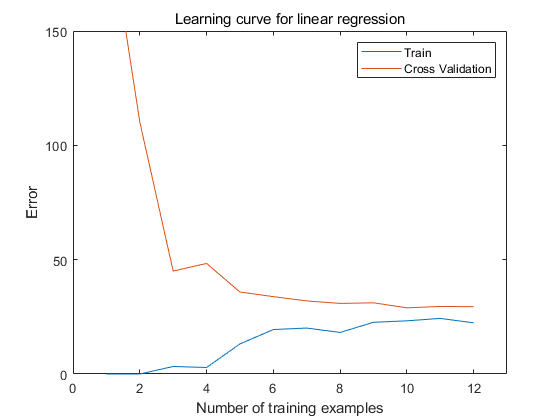


plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 150])

fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1 : m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	205.121096
  	2		0.000000	110.300366
  	3		3.286595	45.010231
  	4		2.842678	48.368911
  	5		13.154049	35.865165
  	6		19.443963	33.829962
  	7		20.098522	31.970986
  	8		18.172859	30.862446
  	9		22.609405	31.135998
  	10		23.261462	28.936207
  	11		24.317250	29.551432
  	12		22.373906	29.433818


## =========== Part 6: Feature Mapping for Polynomial Regression =============

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
% X_poly_test = bsxfun(@minus, X_poly_test, mu);
% X_poly_test = bsxfun(@rdivide, X_poly_test, sigma);
X_poly_test = (X_poly_test - mu) ./ sigma;
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
% X_poly_val = bsxfun(@minus, X_poly_val, mu);
% X_poly_val = bsxfun(@rdivide, X_poly_val, sigma);
X_poly_val = (X_poly_val - mu) ./ sigma;
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  -0.362141  
  -0.755087  
  0.182226  
  -0.706190  
  0.306618  
  -0.590878  
  0.344516  
  -0.508481  


## =========== Part 7: Learning Curve for Polynomial Regression =============

lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.419127e-01
Iteration    11 | Cost: 7.790976e-01
Iteration    12 | Cost: 6.726696e-01
Iteration    13 | Cost: 6.415873e-01
Iteration    14 | Cost: 6.040388e-01
Iteration    15 | Cost: 4.739322e-01
Iteration    16 | Cost: 4.604849e-01
Iteration    17 | Cost: 4.404045e-01
Iteration    18 | Cost: 4.326139e-01
Iteration    19 | Cost: 4.153026e-01
Iteration    20 | Cost: 4.134929e-01
Iteration    21 | Cost: 3.729772e-01
Iteration    22 | Cost: 3.583363e-01
Iteration    23 | Cost: 3.498355e-01
Iteration    24 | Cost: 3.281107e-01
Iteration    25 | Cost: 3.272159e-01
Iteration    26 | Cost: 2.688206e-01
Iteration    27 | Cost: 2.619243e-01
I

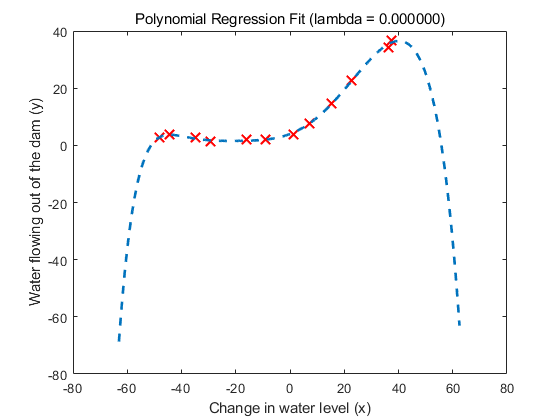

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p); % 图像拟合
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));

[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

当前是第1个样本
Iteration     1 | Cost: 3.386454e-01
Iteration     2 | Cost: 0.000000e+00
当前是第2个样本
Iteration     1 | Cost: 5.373343e-02
Iteration     2 | Cost: 2.656989e-04
Iteration     3 | Cost: 1.480972e-05
Iteration     4 | Cost: 2.814173e-09
Iteration     5 | Cost: 2.813661e-09
Iteration     6 | Cost: 1.423915e-09
Iteration     7 | Cost: 2.500145e-10
Iteration     8 | Cost: 3.072962e-15
Iteration     9 | Cost: 1.239021e-17
Iteration    10 | Cost: 6.717644e-30
Iteration    11 | Cost: 4.437343e-31
Iteration    12 | Cost: 2.465190e-31
Iteration    13 | Cost: 6.162976e-32
Iteration    14 | Cost: 0.000000e+00
当前是第3个样本
Iteration     1 | Cost: 3.023381e+01
Iteration     2 | Cost: 9.745401e-01
Iteration     3 | Cost: 4.827305e-01
Iteration     4 | Cost: 1.170249e-02
Iteration     5 | Cost: 9.696908e-04
Iteration     6 | Cost: 5.299258e-04
Iteration     7 | Cost: 1.985836e-04
Iteration     8 | Cost: 6.032119e-05
Iteration     9 | Cost: 6.225212e-07
Iteration    10 | Cost: 3.894758e-07
Iteration  

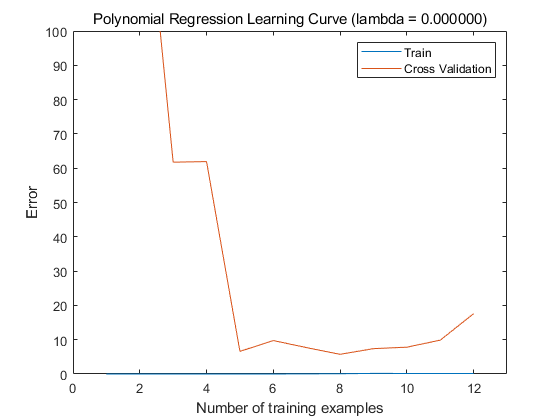

plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

fprintf('Polynomial Regression (lambda = %f)\n\n', lambda);

Polynomial Regression (lambda = 0.000000)



fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1 : m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	160.721900
  	2		0.000000	160.121510
  	3		0.000000	61.754825
  	4		0.000000	61.928895
  	5		0.000000	6.597428
  	6		0.002498	9.748793
  	7		0.043218	7.692405
  	8		0.073885	5.748689
  	9		0.173921	7.393700
  	10		0.157169	7.820808
  	11		0.157823	9.865492
  	12		0.132052	17.594227


## =========== Part 8: Validation for Selecting Lambda =============

[lambda_vec, error_train, error_val] = validationCurve(X_poly, y, X_poly_val, yval);

当前是第1次测试
Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.419127e-01
Iteration    11 | Cost: 7.790976e-01
Iteration    12 | Cost: 6.726696e-01
Iteration    13 | Cost: 6.415873e-01
Iteration    14 | Cost: 6.040388e-01
Iteration    15 | Cost: 4.739322e-01
Iteration    16 | Cost: 4.604849e-01
Iteration    17 | Cost: 4.404045e-01
Iteration    18 | Cost: 4.326139e-01
Iteration    19 | Cost: 4.153026e-01
Iteration    20 | Cost: 4.134929e-01
Iteration    21 | Cost: 3.729772e-01
Iteration    22 | Cost: 3.583363e-01
Iteration    23 | Cost: 3.498355e-01
Iteration    24 | Cost: 3.281107e-01
Iteration    25 | Cost: 3.272159e-01
Iteration    26 | Cost: 2.688206e-01
Iteration    27 | Cost: 2.619

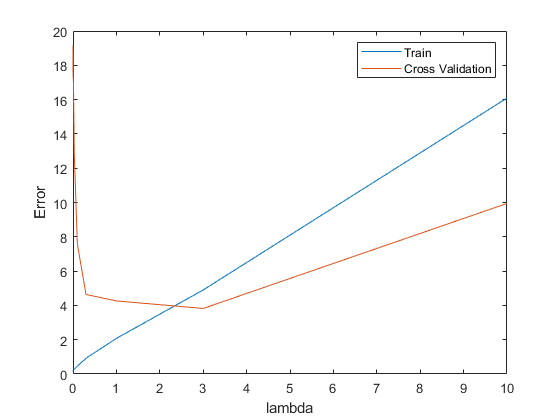

close all;
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');

fprintf('lambda\t\tTrain Error\tValidation Error\n');

lambda		Train Error	Validation Error


for i = 1:length(lambda_vec)
	fprintf(' %f\t%f\t%f\n', ...
            lambda_vec(i), error_train(i), error_val(i));
end

 0.000000	0.132052	17.594227
 0.001000	0.168504	19.151418
 0.003000	0.175454	17.425553
 0.010000	0.221654	17.021792
 0.030000	0.281849	12.828857
 0.100000	0.459318	7.587014
 0.300000	0.921760	4.636833
 1.000000	2.076188	4.260625
 3.000000	4.901351	3.822907
 10.000000	16.092213	9.945508


对测试集进行测试验证

lambda_test = 3;
[~, error_test] = learningCurve(X_poly, y, X_poly_test, ytest, lambda_test);

当前是第1个样本
Iteration     1 | Cost: 9.061563e-01
Iteration     2 | Cost: 3.494525e-02
Iteration     3 | Cost: 3.301806e-02
Iteration     4 | Cost: 1.414663e-02
Iteration     5 | Cost: 1.410563e-03
Iteration     6 | Cost: 1.347257e-03
Iteration     7 | Cost: 1.166458e-04
Iteration     8 | Cost: 3.528311e-07
Iteration     9 | Cost: 1.335616e-07
Iteration    10 | Cost: 3.094671e-13
Iteration    11 | Cost: 3.006885e-13
Iteration    12 | Cost: 9.540107e-14
Iteration    13 | Cost: 8.621389e-29
Iteration    14 | Cost: 4.848384e-30
Iteration    15 | Cost: 1.256075e-31
Iteration    16 | Cost: 1.202497e-31
Iteration    17 | Cost: 5.696111e-32
Iteration    18 | Cost: 1.121777e-32
Iteration    19 | Cost: 2.102075e-34
Iteration    20 | Cost: 2.370864e-63
Iteration    21 | Cost: 4.648519e-65
Iteration    22 | Cost: 8.117423e-93
Iteration    23 | Cost: 4.675678e-97
Iteration    24 | Cost: 7.501737e-123
Iteration    25 | Cost: 1.859642e-126
Iteration    26 | Cost: 4.280529e-152
Iteration    27 | Cost: 1.

error_test(end)

ans = 3.8599